clear

% Opgave 22.1a,

dydt = @(t,y) y.*t.^3 - 1.5.*y;

y0 = 1; h = 0.5; h2 = 0.25;

span = [0, 2];

[t,y,iter] = eulode(dydt,span,y0,h);
[t2,y2,iter2] = eulode(dydt,span,y0,h2);

dy_dt = dydt(t,y);
dy_dt2 = dydt(t2,y2);

disp(table(iter, t,y,dy_dt))

    iter     t        y          dy_dt  
    ____    ___    ________    _________

     0        0           1         -1.5
     1      0.5        0.25     -0.34375
     2        1    0.078125    -0.039062
     3      1.5    0.058594      0.10986
     4        2     0.11353      0.73792



disp(table(iter2, t2,y2,dy_dt2))

    iter2     t2       y2        dy_dt2  
    _____    ____    _______    _________

      0         0          1         -1.5
      1      0.25      0.625     -0.92773
      2       0.5    0.39307     -0.54047
      3      0.75    0.25795      -0.2781
      4         1    0.18842    -0.094212
      5      1.25    0.16487     0.074707
      6       1.5    0.18355      0.34415
      7      1.75    0.26959       1.0404
      8         2    0.52969        3.443



clear
syms y(t)
eqn = diff(y,t) == y*t^3 - 1.5*y;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = {\mathrm{e}}^{\frac{t\,\left(t^{3}-6\right)}{4}}$$

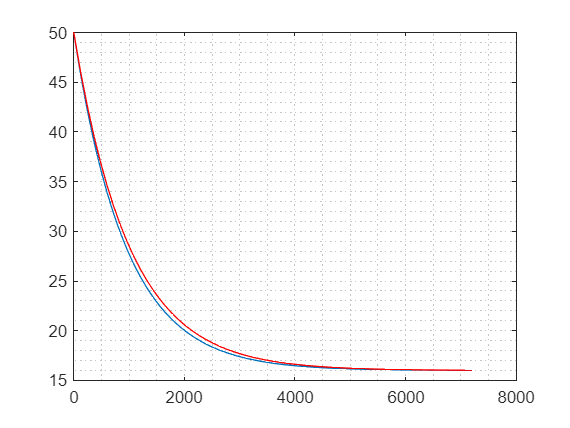

% opgave 22.3


phi = 2508;
qm = 0.1;
tind = 10;  t0 = 50;
m = 100;
c = 4180;

tau_span = [0, 7200];

dtdtau = @(tau,t) (phi - qm*c*(t-tind))/(m*c);

[tau,t, iter] = eulode(dtdtau, tau_span,t0, 120);

%disp(table(iter, t, tau))

plot(tau, t), grid("minor")
hold on

t_ana = 34*exp(-0.001*tau)+16;

plot(tau, t_ana,'r')

hold off